% 读取图像
clear
img = imread('演示文稿1.png')

img = 256×256×3 uint8 数组
img(:,:,1) =

   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255   255 

% 转换为灰度图像
gray_img = rgb2gray(img);
dou_img = ones(256) - im2double(gray_img)

dou_img =      0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0     0     0     0     0   

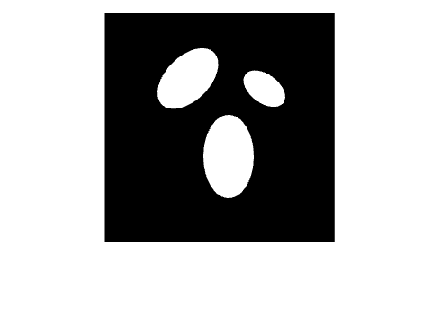

imshow(dou_img)

% 使用 Hough 变换检测圆形
% [centers, radii] = imfindcircles(gray_img, [20 50], 'ObjectPolarity', 'bright', 'Sensitivity', 0.9)
% 
% % 显示原始图像
% imshow(img);
% hold on;
% 
% % 标记检测到的圆形
% viscircles(centers, radii, 'EdgeColor', 'b')
% 
% % 显示圆心
% plot(centers(:,1), centers(:,2), 'r+', 'MarkerSize', 10, 'LineWidth', 2);
% 
% hold off;
% title('检测并标记圆形');